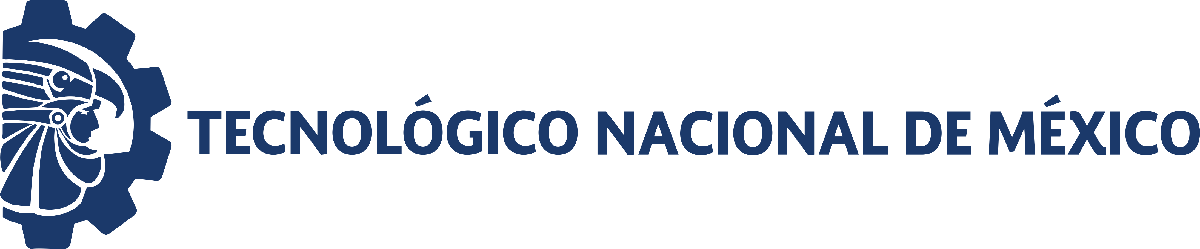                                 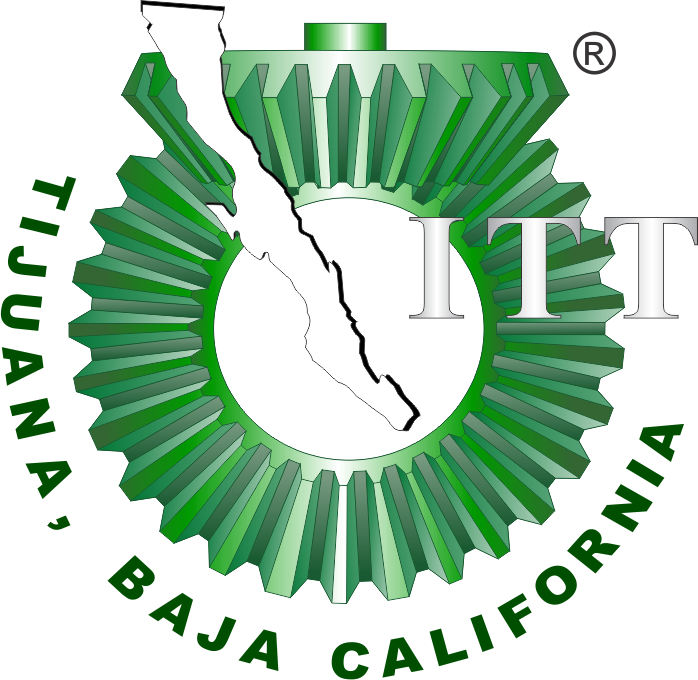

# Práctica final: Sistema respiratorio con asma 

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

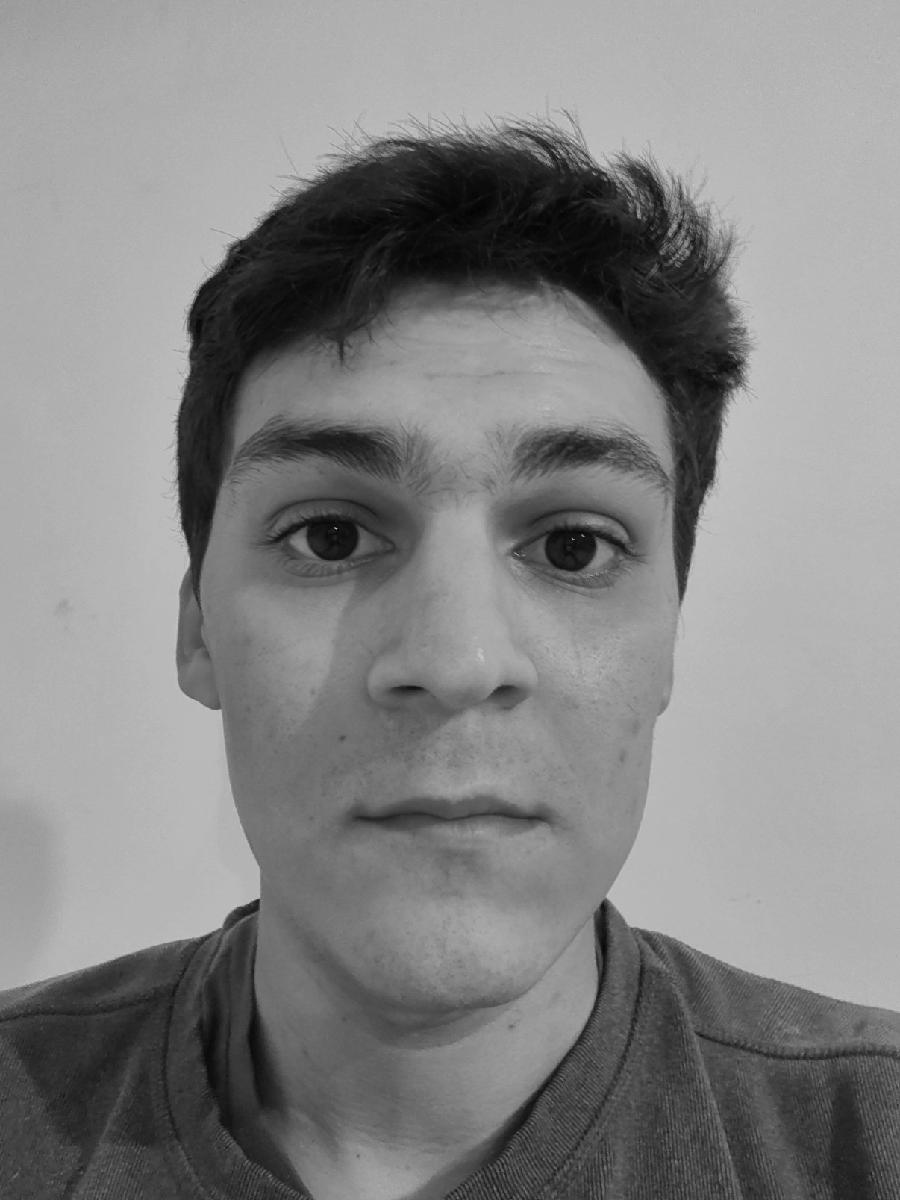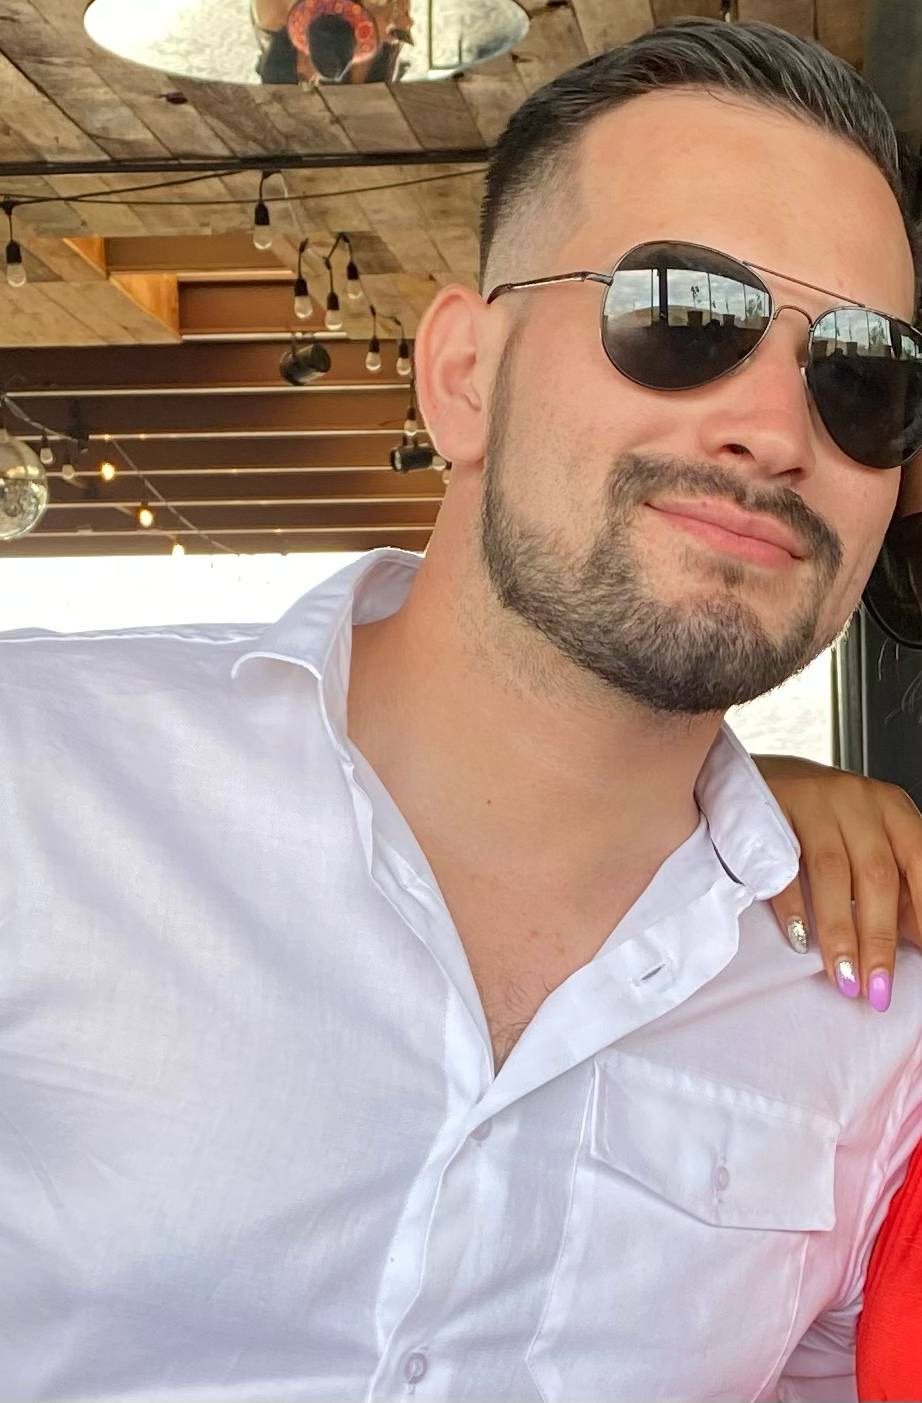

Nombre del alumno: Diego Raul Torres Velez; Villaseñor Lopez Diego David

Número de control: 22210429; 22210431

Correo institucional: l22210429**@tectijuana.edu.mx; **l22210431**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend='10';
file='Torres22210429';
open_system(file);
parameters.Stoptime=tend;
parameters.Solver='ode15';
parameters.MaxStep='1E-3';
Controlador='PI';

## Respuesta al impulso

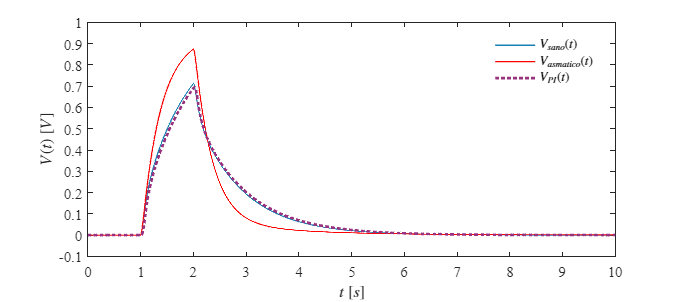

Signal='Impulso';
x=sim(file,parameters);
plotsignals(x.t,x.Ve,x.Vs,x.VPI,Signal)

## Funcion: Respuesta a las señales 

function plotsignals(t,Ve,Vs,VPI,Signal)
    set(figure(),'Color','w')
    set(gcf,'units','Centimeters','Position',[1,1,18,8])
    set(gca,'FontName','Times New Roman')
    fontsize(11,'points')
    rojo=[1,0,0];
    morado=[0.6,0.2,0.5];
    azul=[0.1,0.5,0.7];
    hold on;grid off; box on;

    plot(t,Ve,'-','LineWidth',1,'Color',azul)
    plot(t,Vs,'-','LineWidth',1,'Color',rojo)
    plot(t,VPI,':','LineWidth',2,'Color',morado)

    xlabel('$t$ $[s]$','Interpreter','latex')
    ylabel('$V(t)$ $[V]$','Interpreter','latex')
    
    L=legend('$V_{sano}(t)$','$V_{asmatico}(t)$','$V_{PI}(t)$');
    set(L,'Interpreter','Latex','Location','Best','Box','Off')
    
    if Signal=="Impulso"
    xlim([0,10]); xticks(0:1:10)
    ylim([-0.1,1]); yticks(-0.1:0.1:1)

    end
   
end